This is a program to calculate "Cost Estimation"

1) Cost of ship:

Construction Cost

shipconcost = 116000000

shipconcost = 116000000

Operation cost

Operation cost Parameters

  shipcrew  = 201196; % crew fee
  mr = 50000;  % maintenance and raparing fee
  ac = 25000;  % Admin and charges
  lub = 6000;  % Lub oil fee
  insu = 600000; % insurance fee
  ps = 50000; % provisions and stores fee

Total annual operation cost

shipopetotalannu = shipcrew + mr + ac + lub + insu + ps

shipopetotalannu = 932196

 Total Operation Cost for LLC (20 years)

shipopetotal = shipopetotalannu * 20

shipopetotal = 18643920

Total ship cost

totalshipcost = shipconcost+shipopetotal

totalshipcost = 134643920

2) Cost of REfueling Aircrafts

Number of Refueling Aircraft: Desing vector

    numrair = 1

numrair = 1

Operation Cost (DOC) Paramaters

    aircrew = 0; % pilot wages and benefits. We utilize UAV and this cost becomes "0"
    fuel =489; % fuel cost 
    ma = 548; % maitenance fee
    ow = 923; % owenership fee

Total Operation Cost Per Block-Hour

airopetotal = aircrew + fuel + ma + ow 

airopetotal = 1960

Total Operation Cost in annual

airopeannual = airopetotal * 24 * 365

airopeannual = 17169600

Total Operation Cost for 20 years

airopetotalLLC = airopeannual * 20 * numrair

airopetotalLLC = 343392000

Construction Cost Estimation by utilizing catalogue value

airconcost = 11900000

airconcost = 11900000

airconcosttotal = airconcost * numrair

airconcosttotal = 11900000

Total cost for refueling airplane

totalaircost = airopetotalLLC + airconcosttotal

totalaircost = 355292000

Figure of Cost Estimation

airopetotalLLC = 343392000

airconcost = 11900000

airconcosttotal = 11900000

totalaircost = 355292000

y = 355292000

airopetotalLLC = 686784000

airconcost = 11900000

airconcosttotal = 23800000

totalaircost = 710584000

y = 710584000

airopetotalLLC = 1.0302e+09

airconcost = 11900000

airconcosttotal = 35700000

totalaircost = 1.0659e+09

y = 1.0659e+09

airopetotalLLC = 1.3736e+09

airconcost = 11900000

airconcosttotal = 47600000

totalaircost = 1.4212e+09

y = 1.4212e+09

airopetotalLLC = 1.7170e+09

airconcost = 11900000

airconcosttotal = 59500000

totalaircost = 1.7765e+09

y = 1.7765e+09

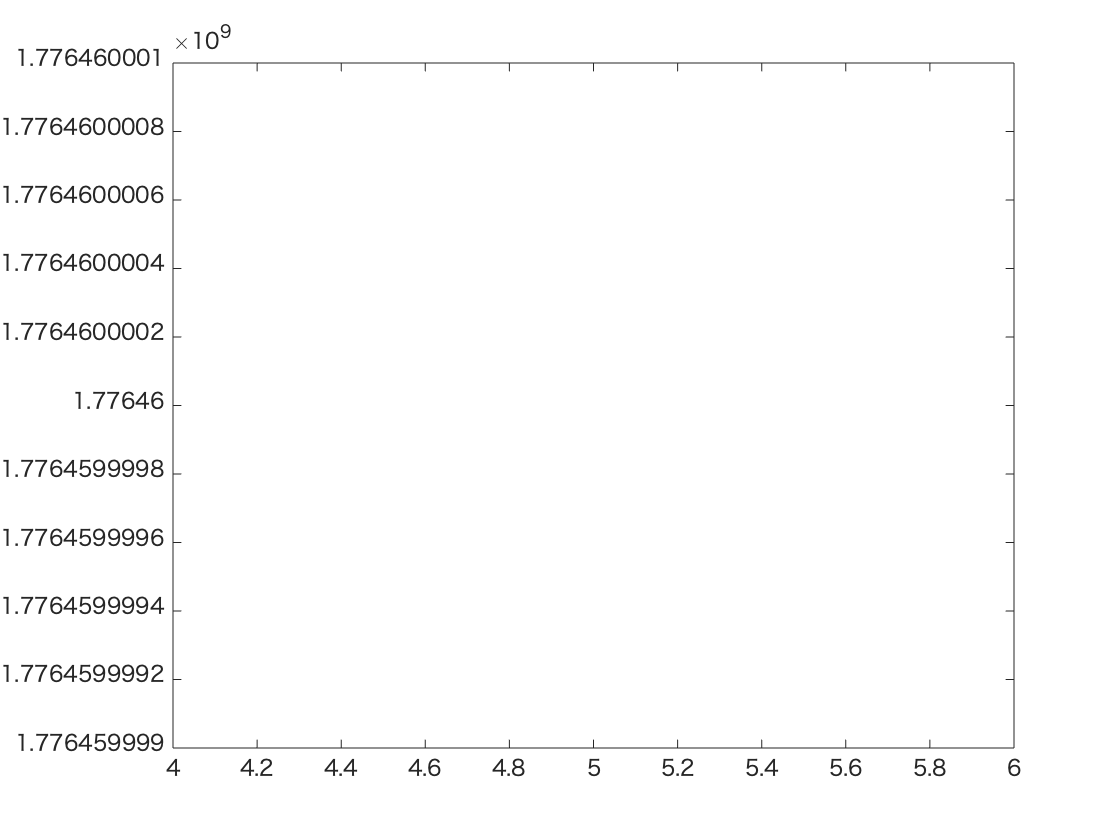

for numrair = 1:5
    airopetotalLLC = airopeannual * 20 * numrair
    airconcost = 11900000
    airconcosttotal = airconcost * numrair
    totalaircost = airopetotalLLC + airconcosttotal
    y(:) = totalaircost
    plot(numrair,y,'r--')
end

Figure

plot(numrair,y,'r--')

The following is other estimation by utilizing Roskam method

W_to is a Design Vector

   logwto = log(60000)

logwto = 11.0021

   AMP1 = 1/log(3.3191+0.8043*logwto)

AMP1 = 0.4002

   W_to = 60000;
   AMP = 1/(log(3.3191+0.8043*log(W_to)))

AMP = 0.4002

 Total cost for ship and refueling aircafts

 Totalcost = totalshipcost + totalaircost 

Totalcost = 1.9111e+09